1번 문제

%함수의 근
r1=fzero(@lhj_25012400_func_1,[0 1])

r1 = 0

r2=fzero(@lhj_25012400_func_1,[1 2])

r2 = 1.3606

%최소값
fminbnd(@lhj_25012400_func_1, 0, 4)

ans = 0.7101

%구한 답이 전역에서 최소인 것인지 증명

%미분했을 때 x의 값
x1=acos(0.15)/2

x1 = 0.7101

x2=((2*pi)-acos(0.15))/2

x2 = 2.4315

%미분했을 때 x의 값이 함수에서의 함수 값
f1=lhj_25012400_func_1(x1)

f1 = -0.7757

f2=lhj_25012400_func_1(x2)

f2 = 1.7181

%끝 값
f0=lhj_25012400_func_1(0)

f0 = 0

f4=lhj_25012400_func_1(4)

f4 = 0.2106


% 전역 최소 비교
global_min = min([f0,f1,f2,f4])

global_min = -0.7757

2번 문제

h=100;
v0=50;
g=9.81;
t=lhj_25012400_func_2(h,v0,g)

t =     2.7324    7.4612


3번 문제

global V
V=10;
%최소값
r_min = fminbnd(@lhj_25012400_func_3, 0.1, 10)

r_min = 10.0000

h_min = (3*V)/(pi*r_min^2)

h_min = 0.0955

%그래프 그리기
r = linspace(0.1,10,100)

r =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


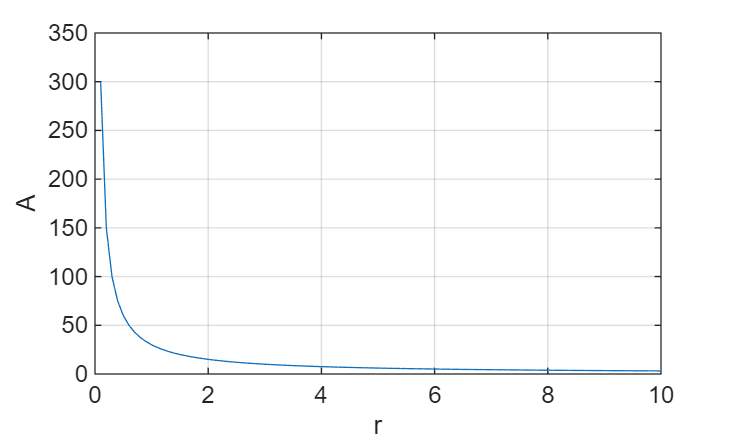

plot(r, lhj_25012400_func_3(r))
xlabel('r')
ylabel('A')
grid on

%10증가
A_min = lhj_25012400_func_3(r_min)

A_min = 3.1623

r_range = r(lhj_25012400_func_3(r) <= 1.1*A_min)

r_range =     9.1000    9.2000    9.3000    9.4000    9.5000    9.6000    9.7000    9.8000    9.9000   10.0000



min(r_range)

ans = 9.1000

max(r_range)

ans = 10

4번 문제

f = @(x) 10*exp(-2*x)

f = 다음 값을 갖는 function_handle:
    @(x)10*exp(-2*x)


x = linspace(0, 2, 100)

x =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899


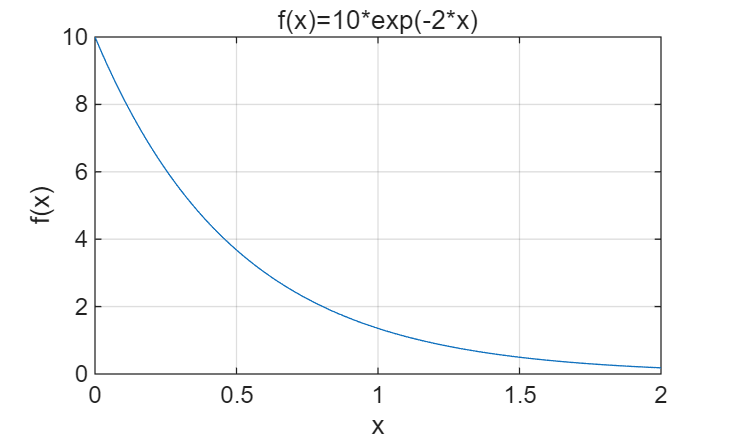


plot(x, f(x))
xlabel('x')
ylabel('f(x)')
title('f(x)=10*exp(-2*x)')
grid on

5번 문제

f=@(x) 30*(x.^2)-300*x+4

f = 다음 값을 갖는 function_handle:
    @(x)30*(x.^2)-300*x+4


x=linspace(0,10,100)

x =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


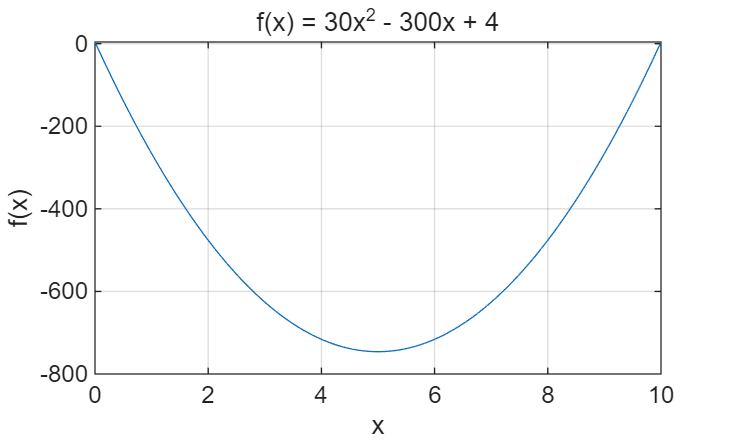


plot(x,f(x))
xlabel('x')
ylabel('f(x)')
title('f(x) = 30x^2 - 300x + 4')
grid on


fminbnd(f,0,10)

ans = 5.0000

f(fminbnd(f,0,10))

ans = -746

6번 문제

f = @(x) x.^2

f = 다음 값을 갖는 function_handle:
    @(x)x.^2


g = @(y) 3*cos(y)

g = 다음 값을 갖는 function_handle:
    @(y)3*cos(y)


h = @(z) 6*exp(z)

h = 다음 값을 갖는 function_handle:
    @(z)6*exp(z)


F = @(x) h(g(f(x))) 

F = 다음 값을 갖는 function_handle:
    @(x)h(g(f(x)))



x = linspace(0, 4, 100)

x =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798


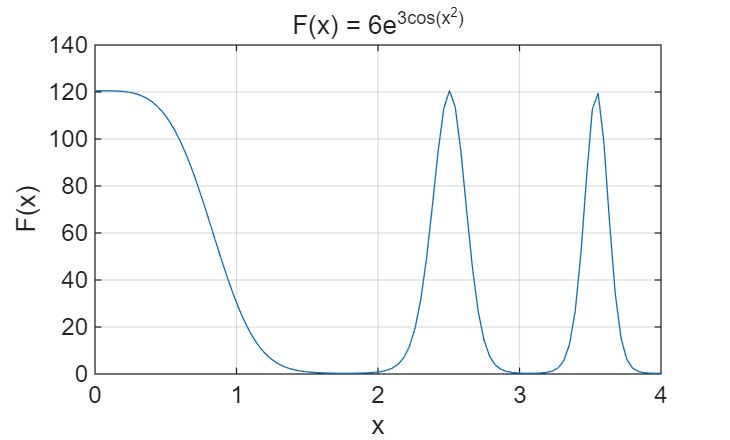


plot(x, F(x))
xlabel('x')
ylabel('F(x)')
title('F(x) = 6e^{3cos(x^2)}')
grid on